% Line-tracking robot simulation
clear all
close all
clc

## Create the path

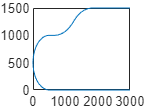

[X,Y] = Path_create;

## Initial parameters

Robot dimension

r = 32.5; %wheel radius
b = 210; %distance between 2 wheel
d = 200; %distance between wheel axis midpoint to sensors board midpoint
L_sensor = 110; %length of sensor board

% Robot's initial condition
x_r(1) = 3000;
y_r(1) = 0;
theta_r(1) = pi;
e(1) = 0;
rpm_l(1) = 0;
rpm_r(1) = 0;
w_l(1) = 0;
w_r(1) = 0;

% PID gain
Kp = 233;
Ki = 11;
Kd = 0.8;

%
dt = 0.003;
i = 1;
t(1) = 0.003;
% v(1)=0;
% a(1)=0;


## Simulation

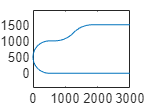

hold on
axis equal

ax=gca;
ax.NextPlot = 'replaceChildren';

while (i<120*length(X)+2)
    i = i + 1;
    t(i) = dt*i;
    error = Sensor(x_r(i-1),y_r(i-1),theta_r(i-1));
    e(i) = error;
    pid = Kp*e(i) + Ki*(e(i-1)+e(i))*dt + Kd*(e(i)-e(i-1))/dt;
    %pid = -pid;
    pid = -pid*0.2794*b/r;
    pwm_l = (88 + pid);
    pwm_l = max(60,min(100,pwm_l));
    pwm_r = (88 - pid);
    pwm_r = max(60,min(100,pwm_r));
    %Transfer function motor 1    
    drpm_l = 5.55*pwm_l - 5.51*rpm_l(i-1);
    rpm_l(i) = rpm_l(i-1) + drpm_l*dt;
    w_l(i) = rpm_l(i)*2*pi/60;
    %Transfer function motor 2   
    drpm_r =  5.852*pwm_r - 5.809*rpm_r(i-1);
    rpm_r(i) = rpm_r(i-1) + drpm_r*dt;      
    w_r(i) = rpm_r(i)*2*pi/60;
    dk(i)=pid; %monitor the control variable
    
    P_dot = [r/2*cos(theta_r(i-1)) r/2*cos(theta_r(i-1));
             r/2*sin(theta_r(i-1)) r/2*sin(theta_r(i-1));
             r/b                                   -r/b]*[w_r(i); w_l(i)];
    
%     v(i) = sqrt(P_dot(1)^2 + P_dot(2)^2);
%     a(i) = (v(i) - v(i-1))/dt;
    x_r(i) = x_r(i-1) + P_dot(1)*dt;
    y_r(i) = y_r(i-1) + P_dot(2)*dt;
    theta_r(i) = theta_r(i-1) + P_dot(3)*dt;
    
   %x_t(i) = x_r(i) + d*cos(theta_r(i));
  % y_t(i) = y_r(i) + d*sin(theta_r(i));
    
end

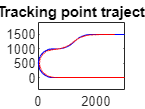

plot(X,Y,'b',x_r,y_r,'r');title("Tracking point trajectory");

%plot(X,Y,'b',x_t,y_t,'r')

## Plot result

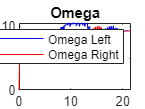

figure(2);
plot(t,w_l,'b',t,w_r,'r');
legend('Omega Left', 'Omega Right');title("Omega");

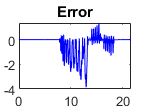


figure(3)
plot(t,e,'b');title("Error");


% 
% figure('Name','Control variable');
% plot(t,dk/1000,'b');
